Console preparation

clc;
close all; 
warning('off', 'all');

Import the data for the step response of the fan

open('rpm.fig'); 
a = get(gca,'Children');  
obj_r = a(2);  
x_sr_fan = obj_r.XData;
y_sr_fan = obj_r.YData; % Drehzahl [RPM]
close(gcf);

open('rpm_for_alpha2.fig'); 
b = get(gca,'Children');  
obj_r_alpha2 = b(2);  
x_constant_w = obj_r_alpha2.XData;
y_constant_w = obj_r_alpha2.YData; 
close(gcf);

Cut out only the last 60 s of the data which is the size of the actual window in the scope

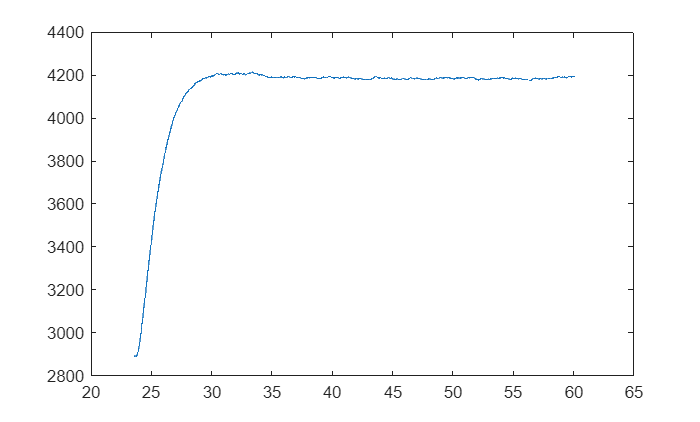

time_limit_sr = max(x_sr_fan) - 36.5; 
idx_sr = x_sr_fan >= time_limit_sr;
x_sr_fan = x_sr_fan(idx_sr);
y_sr_fan = y_sr_fan(idx_sr);
t_r = x_sr_fan(:);
Ts_r = mean(diff(t_r));


time_limit_cw = max(x_constant_w)-60; 
idx_cw = x_constant_w >= time_limit_cw;
x_constant_w = x_constant_w(idx_cw);
y_constant_w = y_constant_w(idx_cw);
t_cw = x_constant_w(:);        % time vector (column)
Ts_cw = mean(diff(t_cw));      % average sample time

plot(t_r,y_sr_fan);

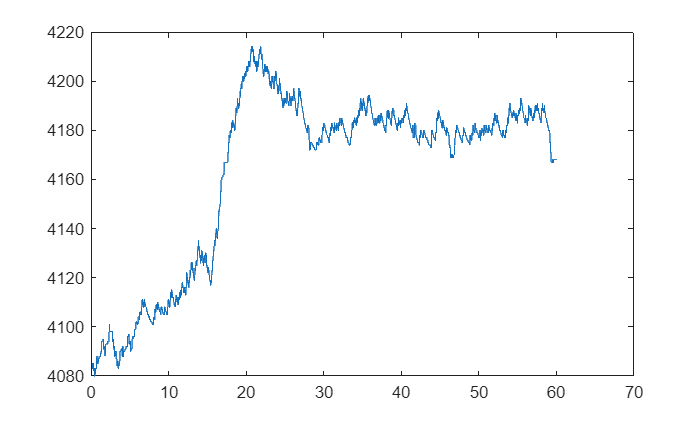

plot(t_cw,y_constant_w);

avg_rpm_constant = (4313+4117)/2

avg_rpm_constant = 4215

w_constant = avg_rpm_constant % (2*pi*avg_rpm_constant)/60

w_constant = 4215

Variable values

y_rotations = y_sr_fan;%(2*pi*y_sr_fan)/60;
kl = 5.5e-5;
m = 2.7e-3;
Ab = 1.257e-3;
Atube = 1.452e-3; 
Agap = Atube - Ab;
g = 9.81;
rotations_at_ss = 4200; % rpm
w = rotations_at_ss % (2*pi*rotations_at_ss)/60

w = 4200

duty_cycle = [0 2 5 8 10 12];  % duty cycle
rpm     = [2950 3300 3650 4050 4250 4500]; 
w_duty_cycle = (2*pi*rpm)/60

w_duty_cycle =   308.9233  345.5752  382.2271  424.1150  445.0590  471.2389


Calculation of the coefficients

alpha1 = sqrt(g)/w

alpha1 = 7.4574e-04

alpha3 = g

alpha3 = 9.8100

%z_dot = 0.05; %slope from figure at constant height (height_at_ss.fig)
u = duty_cycle%(duty_cycle / 100) * 5

u =      0     2     5     8    10    12


alpha2 = (alpha1 * w_constant - sqrt(g))/z_dot

alpha2 = 0.2237

alpha2 = alpha1*w_constant/z_dot - sqrt(g)/z_dot 

alpha2 = 0.2237

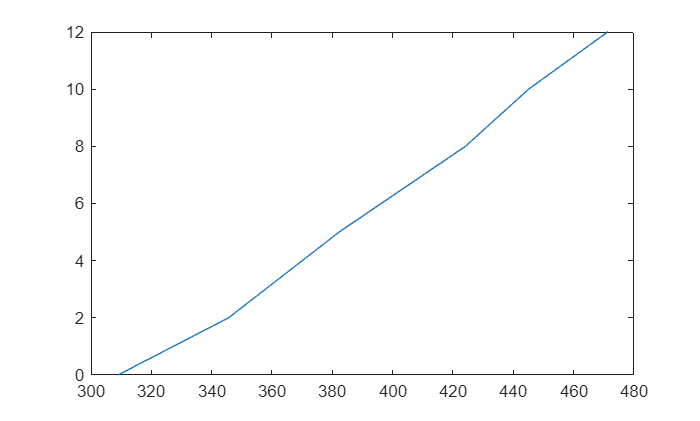

plot(w_duty_cycle,u);

polyfit_of_w = polyfit(w_duty_cycle, u, 1);
m = polyfit_of_w(1);
d = polyfit_of_w(2);
ktau_from_rpm_ramp = 1/m

ktau_from_rpm_ramp = 13.2992

u0 = (d / 100) * 5

u0 = -1.1812

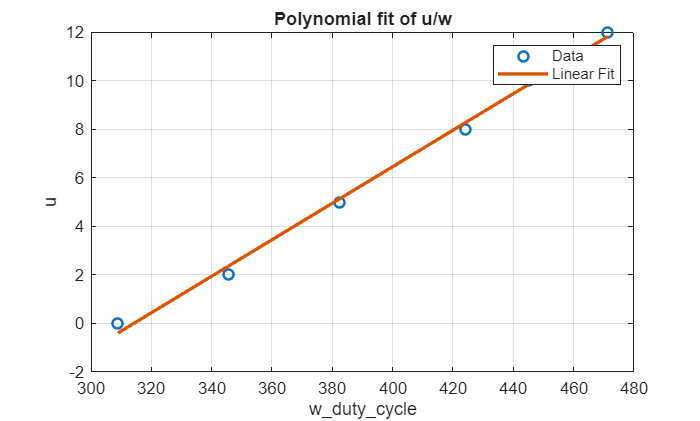

w_fit = linspace(min(w_duty_cycle), max(w_duty_cycle), 200);
u_fit = m * w_fit + d;
figure;
plot(w_duty_cycle, u, 'o', 'MarkerSize', 6, 'LineWidth', 1.5); hold on;
plot(w_fit, u_fit, 'LineWidth', 2);
grid on;

xlabel('w\_duty\_cycle');
ylabel('u');
title('Polynomial fit of u/w');
legend('Data', 'Linear Fit');

y_baseline = mean(y_rotations(1:10)); 
y_shifted = y_rotations(:) - y_baseline; 
U_step = 9.5%(9.5/100)*5

U_step = 9.5000

u = ones(length(y_rotations), 1) * U_step; 
u = u(:);
data_obj = iddata(y_shifted, u, Ts_r); 
sys_tfest_raw = tfest(data_obj, 1, 0);
[num, den] = tfdata(sys_tfest_raw, 'v');
A = num(end); 
a = den(end); 
tau_omega = 1 / a

tau_omega = 1.7217

k_omega = A / a

k_omega = 136.9112

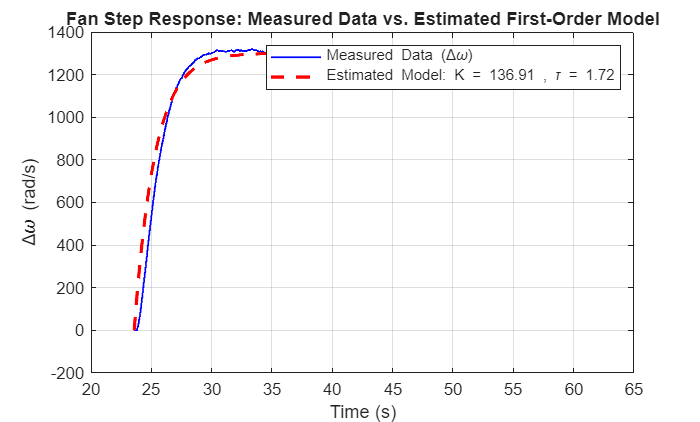

sys_pt1_sim = tf(k_omega, [tau_omega 1]);

t_r = x_sr_fan(:); 

[y_sim, t_sim] = step(sys_pt1_sim, t_r); 
y_sim_scaled = y_sim * U_step;

figure;
plot(t_r, y_shifted, 'b', 'LineWidth', 1); hold on;
plot(t_sim, y_sim_scaled, 'r--', 'LineWidth', 2);
grid on;

xlabel('Time (s)');
ylabel('\Delta\omega (rad/s)');
title('Fan Step Response: Measured Data vs. Estimated First-Order Model');

% --- CORRECTED LEGEND LINE ---
legend_str_k = sprintf('K = %.2f', k_omega);
legend_str_tau = sprintf('\\tau = %.2f', tau_omega);
legend('Measured Data (\Delta\omega)', ['Estimated Model: ' legend_str_k ' , ' legend_str_tau]);

u0        = 0;     % [V]
a  = 4178.75;                % rpm
omega_bar = sqrt(alpha3)/alpha1;
u_bar     = (omega_bar -a) / k_omega + u0;
z0 = 0.15;              % [m] frei wählbar
zdot0 = 0;              % [m/s]
omega0 = omega_bar;     % [rad/s] o. RPM – konsistent mit k_omega 


A = [ 0, 1, 0;
      0, -2*alpha1*alpha2*omega_bar,  2*alpha1^2*omega_bar;
      0, 0, -1/tau_omega ];

B = [0; 0; k_omega/tau_omega];

C = [1 0 0];

D = 0;


state_space_sys = ss(A,B,C,D);

G_lin = tf(state_space_sys)


G_lin =
 
           0.3715
  -------------------------
  s^3 + 1.982 s^2 + 0.814 s
 
Continuous-time transfer function.



%% Controller
% Define the PID controller
Kp = 1; % Proportional gain
Ki = 0.1; % Integral gain
Kd = 0.01; % Derivative gain
C_pid = pid(Kp, Ki, Kd);

% Closed-loop system
sys_cl = feedback(C_pid * G_lin, 1);
PID = pidTuner(G_lin,'PID');

% Tuned parameters
Kp_tuned = Tuned_PID.Kp;

Unable to resolve the name 'Tuned_PID.Kp'.

Ki_tuned = Tuned_PID.Ki;
Kd_tuned = Tuned_PID.Kd;

%fprintf('w_constant_w = %.4f\n', w_constant_w);
fprintf(['alpha1 = %.4f;\n', ...
         'alpha2 = %.4f;\n', ...
         'alpha3 = %.4f;\n', ...
         'tau_estimated = %.4f;\n'], ...
         alpha1, alpha2, alpha3, tau_omega);
fprintf(['alpha1 = %g;\n', ...
         'alpha2 = %g;\n', ...
         'alpha3 = %g;\n', ...
         '%% Lüfter Parameter \n', ...
         'tau_omega = %g;                       %% [s] Zeitkonstante PT1 (aus Messung)\n', ...
         'k_omega = %g;                %% [rpm/%%] K Wert PT1 (aus Messung)\n'], ...
         alpha1, alpha2, alpha3, tau_omega, k_omega);